Matlab code for the Course: **Modelling and Simulation Mechatronics System (2020)**

by Enrico Bertolazzi and Francesco Biral

Dipartimento di Ingegneria Industriale

Università degli Studi di Trento

email: [enrico.bertolazzi@unitn.it](mailto:enrico.bertolazzi@unitn.it)

#### Initialize by cleaning memory and widows

close all;

#### Initialize parameters of the model and instantiate model class

ell     = 1.0;
m       = 1.0;
gravity = 9.81;
ODE     = CrankRod5EQ( ell, m, gravity );

#### Initialize the solver class

solver = ExplicitEuler();
solver.setODE( ODE );

#### **Select the range and the sampling point for the numerical solution**

Tmax = 7.5;
h    = 0.05;
tt   = 0:h:Tmax;

#### Set consistent initial conditions

angle     = -pi/4;
speed     = 0.0;

x_10      = ell*cos(angle);
y_10      = ell*sin(angle);
x_20      = 2*ell*cos(angle);
y_20      = 0;
theta_10  = angle;
theta_20  = angle;
u_10      = -speed*ell*sin(angle);
v_10      = speed*ell*cos(angle);
u_20      = -2*speed*ell*sin(angle);
v_20      = 0;
lambda_10 = -3*cos(angle)*m*(ell*(speed^2)-sin(angle)*gravity)*(1/(4*sin(angle)^2+1));
lambda_20 = -5*sin(angle)*m*(ell*(speed^2)-sin(angle)*gravity)*(1/(4*sin(angle)^2+1));
lambda_30 = -2*cos(angle)*m*(ell*(speed^2)-sin(angle)*gravity)*(1/(4*sin(angle)^2+1));
lambda_40 = m*gravity;
lambda_50 = -2*sin(angle)*m*(ell*(speed^2)-sin(angle)*gravity)*(1/(4*sin(angle)^2+1));
ini       = [ x_10; y_10; x_20; y_20; theta_10; theta_20; ...
              u_10; v_10; u_20; v_20; ...
              lambda_10; lambda_20; lambda_30; lambda_40; lambda_50 ];

#### **Compute numerical solution**

sol = solver.advance( tt, ini );

#### Extract solution

x_1     = sol(1,:);
y_1     = sol(2,:);
x_2     = sol(3,:);
y_2     = sol(4,:);
theta_1 = sol(5,:);
theta_2 = sol(6,:);
u_1     = sol(7,:);
v_1     = sol(8,:);
u_2     = sol(9,:);
v_2     = sol(10,:);

#### Plot the solution

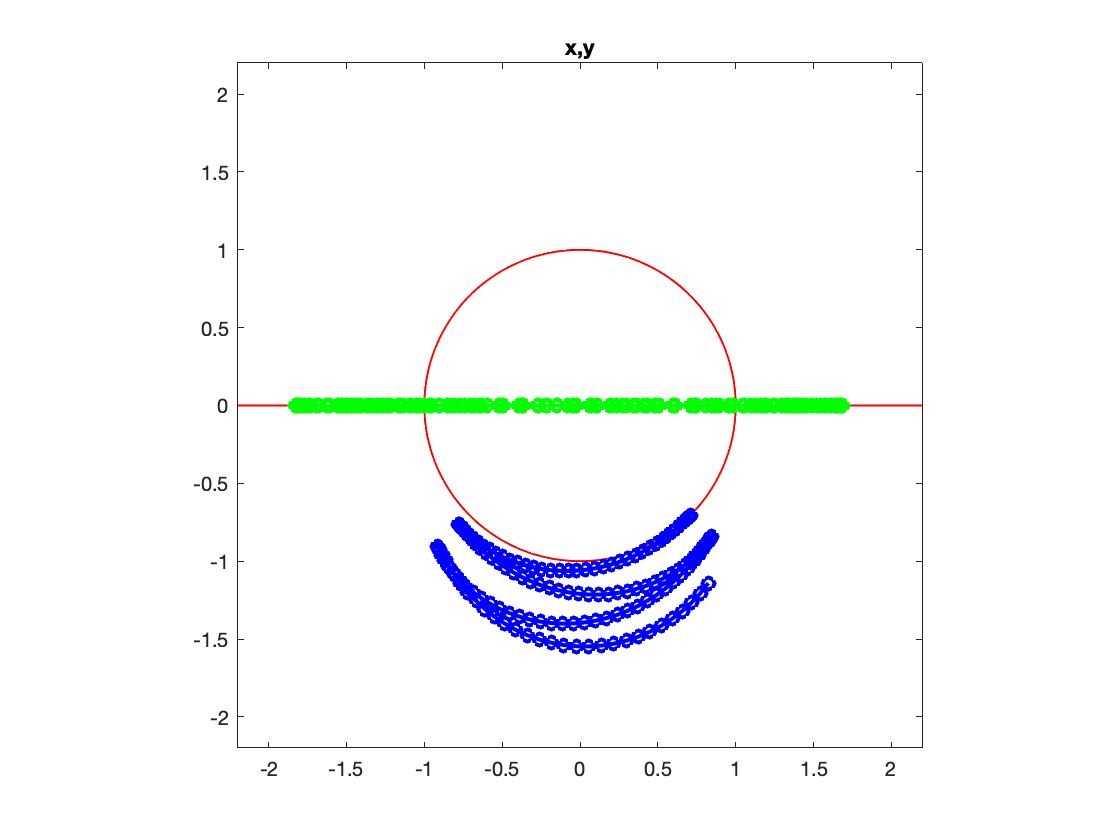

xc1 = ell*cos(0:pi/100:2*pi);
yc1 = ell*sin(0:pi/100:2*pi);
plot( xc1, yc1, '-r', 'Linewidth', 1 );
hold on
axis_lim = ell*2.2;
xc2 = -axis_lim:0.05:axis_lim;
yc2 = 0.0*(-axis_lim:0.05:axis_lim);
plot( xc2, yc2, '-r', 'Linewidth', 1 );
axis equal
plot( x_1, y_1, '-o', 'MarkerSize', 6, 'Linewidth', 2, 'Color', 'blue' );
plot( x_2, y_2, '-o', 'MarkerSize', 6, 'Linewidth', 2, 'Color', 'green' );
xlim([-axis_lim axis_lim])
ylim([-axis_lim axis_lim])
title('x,y');
hold off;

#### Initialize the solver class

solver_I = ImplicitEuler();
solver_I.setODE( ODE );

#### **Compute numerical solution**

sol_I = solver_I.advance( tt, ini );

#### Extract solution

x_1_I     = sol_I(1,:);
y_1_I     = sol_I(2,:);
x_2_I     = sol_I(3,:);
y_2_I     = sol_I(4,:);
theta_1_I = sol_I(5,:);
theta_2_I = sol_I(6,:);
u_1_I     = sol_I(6,:);
v_1_I     = sol_I(7,:);
u_2_I     = sol_I(8,:);
v_2_I     = sol_I(9,:);

#### Plot the solution

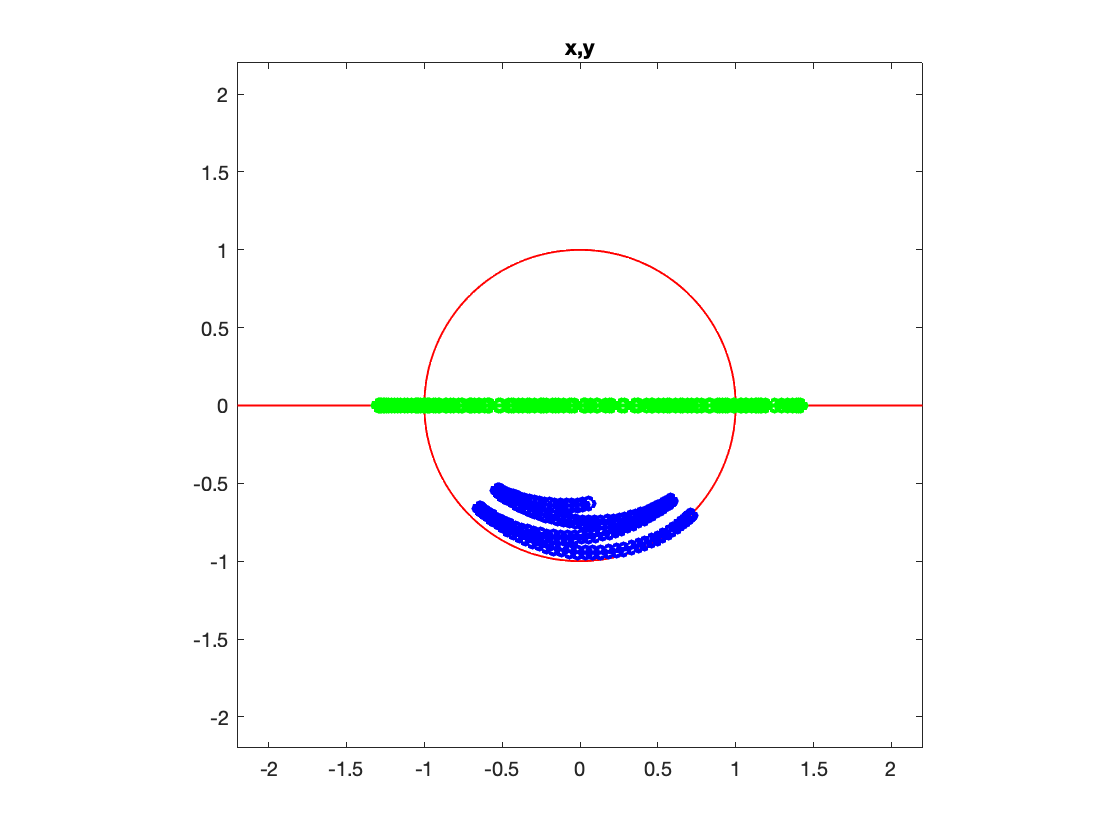

xc1_I = ell*cos(0:pi/100:2*pi);
yc1_I = ell*sin(0:pi/100:2*pi);
plot( xc1_I, yc1_I, '-r', 'Linewidth', 1 );
hold on
axis_lim = ell*2.2;
xc2_I = -axis_lim:0.05:axis_lim;
yc2_I = 0.0*(-axis_lim:0.05:axis_lim);
plot( xc2_I, yc2_I, '-r', 'Linewidth', 1 );
axis equal
plot( x_1_I, y_1_I, '-o', 'MarkerSize', 6, 'Linewidth', 2, 'Color', 'blue' );
plot( x_2_I, y_2_I, '-o', 'MarkerSize', 6, 'Linewidth', 2, 'Color', 'green' );
xlim([-axis_lim axis_lim])
ylim([-axis_lim axis_lim])
title('x,y');
hold off;

#### Initialize the solver class

solver_P = ExplicitEuler_P();
solver_P.setODE( ODE );

#### **Compute numerical solution**

sol_P = solver_P.advance( tt, ini );

Unrecognized method, property, or field 'getDim' for class 'CrankRod5EQ'.

Error in ODEbaseSolver_P/project (line 72)
      [neq,ninv] = self.odeClass.getDim();

Error in ODEbaseSolver_P/advance (

#### Extract solution

x_1_P     = sol_P(1,:);
y_1_P     = sol_P(2,:);
x_2_P     = sol_P(3,:);
y_2_P     = sol_P(4,:);
theta_1_P = sol_P(5,:);
theta_2_P = sol_P(6,:);
u_1_P     = sol_P(6,:);
v_1_P     = sol_P(7,:);
u_2_P     = sol_P(8,:);
v_2_P     = sol_P(9,:);

#### Plot the solution

xc1_P = ell*cos(0:pi/100:2*pi);
yc1_P = ell*sin(0:pi/100:2*pi);
plot( xc1_P, yc1_P, '-r', 'Linewidth', 1 );
hold on
axis_lim = ell*2.2;
xc2_P = -axis_lim:0.05:axis_lim;
yc2_P = 0.0*(-axis_lim:0.05:axis_lim);
plot( xc2_P, yc2_P, '-r', 'Linewidth', 1 );
axis equal
plot( x_1_P, y_1_P, '-o', 'MarkerSize', 6, 'Linewidth', 2, 'Color', 'blue' );
plot( x_2_P, y_2_P, '-o', 'MarkerSize', 6, 'Linewidth', 2, 'Color', 'green' );
xlim([-axis_lim axis_lim])
ylim([-axis_lim axis_lim])
title('x,y');